# **Trajectory Decoding**

clc;
clear;
close all;

#### **Load Data**

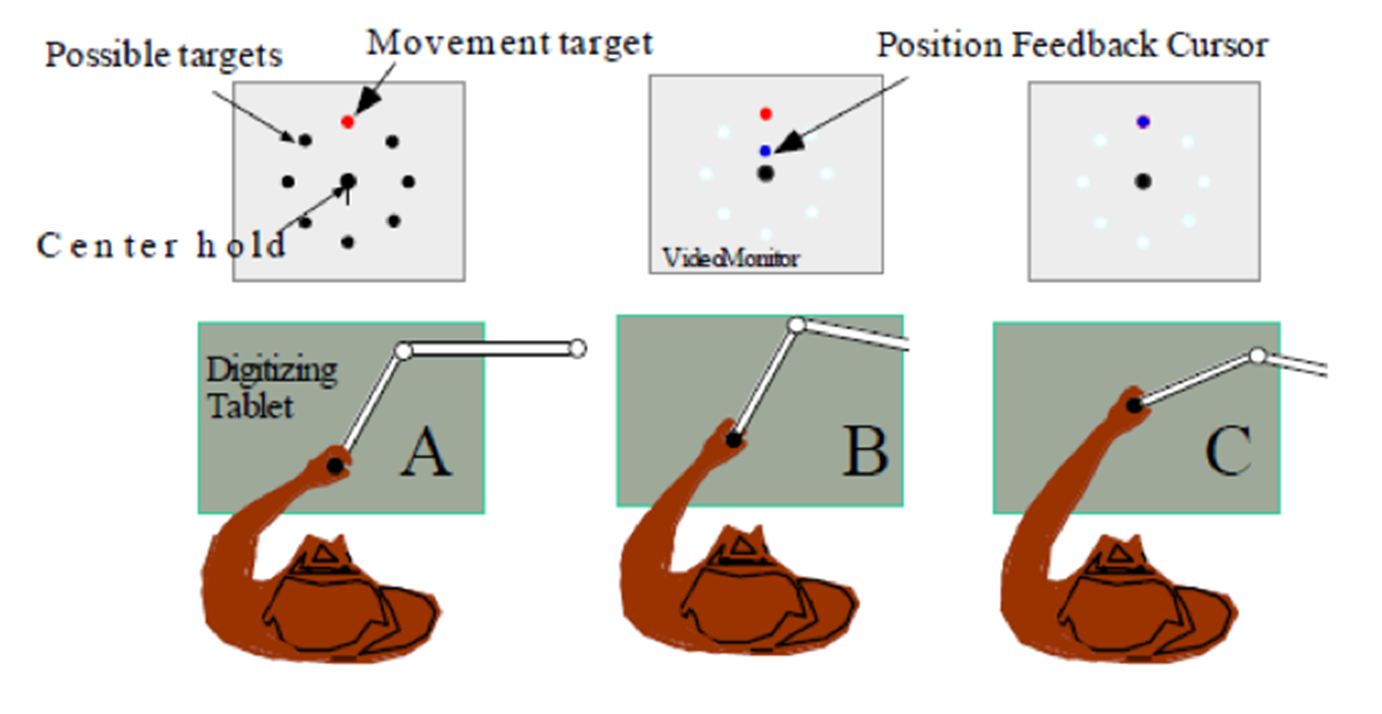

load('data_Flint_2012_e1.mat');
data

#### **Data Processing**

% Behavioral output
hand_pos = {data.HandPos}';

% Directions
dir_list = 0:45:315;
idx_class = [data.class]';
hand_dir = dir_list(idx_class);

% Trial Time
trial_time  = {data.Time};
move_onset  = [data.movementOnset];
move_off    = [data.movementOffset];

#### **Generate Matrix**

n_trial = length(hand_pos)

n_trial = 175

n_neuron = length(data(1).Neuron)

n_neuron = 196

% Generate Trial x Neuron spike_data matrix 
spike_data = cell(n_trial,n_neuron); 
for i = 1:n_trial
    for j = 1:n_neuron
        % Neuron data include the spike timing and LFP data
        spike_data{i,j} = data(i).Neuron(j).Spike;
    end
end

#### **Get Firing rate**

Neural firing rate during reaching (move_onset ~ move_offset)

% Hand position data sampling rate 100 Hz
fs = 100;

% Select the bin size and bin step
bin_size    = 0.1;
overlap     = 0;    % percentage: 0 ~ 1
bin_step    = bin_size - bin_size*overlap;
n_step      = round(bin_step/(1/fs));

FR = cell(n_trial,1);       % (1) Time X Neuron firing rate matrix in cell structure
Pos = cell(n_trial,1);      % (2) Time X cordination matrix in cell structure

for trial = 1:n_trial
    time        = move_onset(trial):n_step:move_off(trial);  % Movement time index
    n_time      = length(time);
    n_neuron    = length(data(1).Neuron); % 196

    % (1) Time X Neuron firing rate matrix
    tmp_fr = zeros(n_time, n_neuron);
    for t = 1:n_time
        for neuron = 1:n_neuron
            % tmp: allocate spike train in given trial and neuron
            tmp = spike_data{trial,neuron};
            % tmp_t: allocate movement time in given trial and t
            tmp_t = trial_time{trial}(time(t));
            % spike count using box car filter
            tmp_fr(t,neuron) = sum(tmp > tmp_t -bin_size/2 & tmp < tmp_t+bin_size/2)/bin_size;
        end
    end
    FR{trial}  = tmp_fr;

    % (2) Time X Coordination matrix
    Pos{trial} = hand_pos{trial}(time,1:2);
end

#### **Data Normalization**

% Calculate the mean and std of each data
mean_fr     = mean(cell2mat(FR),1);
std_fr      = std(cell2mat(FR),[],1);
mean_pos    = mean(cell2mat(Pos),1);
std_pos     = std(cell2mat(Pos),[],1);

% Neuron selection
idx_mask = mean_fr<10;

% Z-score normalization
Z_FR    = cellfun(@minus,FR,repmat({mean_fr},175,1),'UniformOutput',false);
Z_FR    = cellfun(@rdivide,Z_FR,repmat({std_fr},175,1),'UniformOutput',false);
Z_Pos   = cellfun(@minus,Pos,repmat({mean_pos},175,1),'UniformOutput',false);
Z_Pos   = cellfun(@rdivide,Z_Pos,repmat({std_pos},175,1),'UniformOutput',false);

% Calculate velocity
Vel = cellfun(@diff,Z_Pos,'UniformOutput',false);

% Calculate the mean and std of velocity
mean_vel    = mean(cell2mat(Vel),1);
std_vel     = std(cell2mat(Vel),[],1);

% Z-score normalization
Z_Vel = cellfun(@minus,Vel,repmat({mean_vel},175,1),'UniformOutput',false);
Z_Vel = cellfun(@rdivide,Z_Vel,repmat({std_vel},175,1),'UniformOutput',false);

% Add NaN for time alignment
Z_Vel = cellfun(@cat,repmat({1},175,1),repmat({[nan nan]},175,1),Z_Vel,'UniformOutput',false);

#### **Concat the Train Data for Decoding Training**

% Use 90% as a training data
len_train = round(length(hand_dir)*0.9);

% Use one fold out of 5-fold set
cv = cvpartition(hand_dir(1:len_train),'KFold',5);

idx_train = training(cv,1);
idx_val = test(cv,1);

% Use 10% as a test data
idx_test = len_train+1:length(hand_dir);

%% position
% training data
data_train = cell2mat(Z_FR(idx_train)); 
data_train = data_train(:,~idx_mask);
pos_train  = cell2mat(Z_Pos(idx_train));   % training data

% validation data
data_val   = cell2mat(Z_FR(idx_val));
data_val   = data_val(:,~idx_mask);
pos_val    = cell2mat(Z_Pos(idx_val));     % validation data

%% velocity
% training data
vel_train = cell2mat(Z_Vel(idx_train)); 
idx_nan = isnan(vel_train(:,1));        % index for removal

data_train_v = data_train;              % training data
data_train_v(idx_nan,:) = [];
vel_train(idx_nan,:) = [];              % remove nan time point from training data

% validation data
vel_val = cell2mat(Z_Vel(idx_val));
idx_nan = isnan(vel_val(:,1));          % index for removal

data_val_v = data_val;                  % validation data
data_val_v(idx_nan,:) = [];
vel_val(idx_nan,:) = [];                % remove nan time point from validation data

# **Multi Linear Regression (mLR)**

% Position or velocity as a dependent variable (DV)
y_pos = pos_train;
y_vel = vel_train;

% Firing rate matrix as a independent variable (IV)
X_p = data_train;
X_v = data_train_v;

#### `!!!Fill the blank!!!`

[Hint] 

% Train position
beta_pos = inv(X_p'*X_p)*X_p'*y_pos;

% Train velocity
beta_vel = inv(X_v'*X_v)*X_v'*y_vel;

**Test**

% Change subplot dimension if you change the number of training sample
sub_dim = [3 6];

% Test set indexing
data_test = Z_FR(idx_test);
pos_test = Z_Pos(idx_test);
vel_test = Z_Vel(idx_test);

% Figure for plotting decoding result
figure(1)
sgtitle('Position Decoding')
figure(2)
sgtitle('Velocity Decoding')

n_trial     = length(data_test);
pos_pred    = cell(n_trial,1);
pos_rec     = cell(n_trial,1);
vel_pred    = cell(n_trial,1);

for trial = 1:n_trial
    % (1) Postion
    x_test = data_test{trial}(:,~idx_mask);

#### `!!!Fill the blank!!!`

    pos_pred{trial} = x_test*beta_pos;      % Get position by multiplying X and beta

    % for plot
    figure(1)
    subplot(sub_dim(1),sub_dim(2),trial)
    hold on
    plot(pos_test{trial}(1,1),pos_test{trial}(1,2),'k.','MarkerSize',20)
    plot(pos_test{trial}(:,1),pos_test{trial}(:,2),'k','LineWidth',1.8)
    plot(pos_pred{trial}(1,1),pos_pred{trial}(1,2),'.','color',"#0072BD",'MarkerSize',20)
    plot(pos_pred{trial}(:,1),pos_pred{trial}(:,2),'color',"#0072BD",'LineWidth',1.2)
    xlim([-2.5 2.5])
    ylim([-2.5 2.5])
    

    % (2) Velocity
    x_test = data_test{trial}(:,~idx_mask);
    x_test(1,:) = [];                              % Remove first time point

#### `!!!Fill the blank!!!`

    vel_tmp = x_test*beta_vel;                     % Get velocity by multiplying X and beta

    % Reconstruct position by adding velocity
    pos_rec{trial} = pos_test{trial}(1,:);         % Get starting position
    vel_pred{trial} = vel_tmp.*std_vel + mean_vel; % Return to original value

    n_t = length(vel_pred{trial});
    for i = 1:n_t
        % tmp_rec: add current time point velocity to previous pos_rec
        tmp_rec = [pos_rec{trial}(i,1)+vel_pred{trial}(i,1) pos_rec{trial}(i,2)+vel_pred{trial}(i,2)];
        pos_rec{trial} = [pos_rec{trial}; tmp_rec];
    end

    % for plot
    figure(2)
    subplot(sub_dim(1),sub_dim(2),trial)
    hold on
    plot(pos_test{trial}(1,1),pos_test{trial}(1,2),'k.','MarkerSize',20)
    plot(pos_test{trial}(:,1),pos_test{trial}(:,2),'k','LineWidth',1.8)
    plot(pos_rec{trial}(1,1),pos_rec{trial}(1,2),'.','color',"#0072BD",'MarkerSize',20)
    plot(pos_rec{trial}(:,1),pos_rec{trial}(:,2),'color',"#0072BD",'LineWidth',1.2)
    xlim([-2.5 2.5])
    ylim([-2.5 2.5])
end

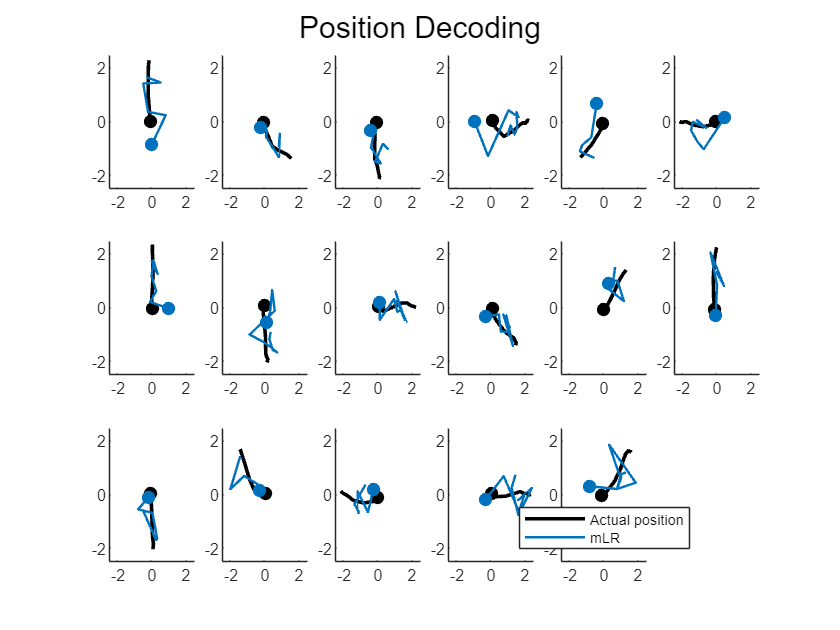

figure(1)
legend('','Actual position','','mLR','Location','Best')

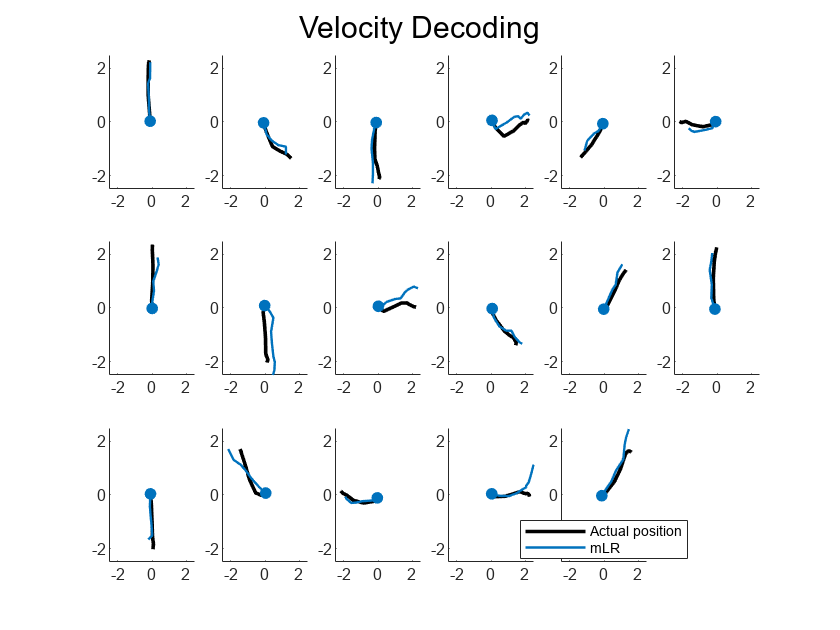

figure(2)
legend('','Actual position','','mLR','Location','Best')

#### **mLR Evaluation**

% Original
tmp = cell2mat(pos_test);
x_pos = tmp(:,1);
y_pos = tmp(:,2);

% (1) For position
tmp = cell2mat(pos_pred);
xhat_pos = tmp(:,1);
yhat_pos = tmp(:,2);

% Get mean absolute error(MAE) between original and predicted
MAE_pos_x = sum(abs(x_pos - xhat_pos))/length(x_pos);
MAE_pos_y = sum(abs(y_pos - yhat_pos))/length(y_pos);

% Get correlation between original and predicted
CC_pos_x = corr(x_pos,xhat_pos);
CC_pos_y = corr(y_pos,yhat_pos);

% (2) For velocity
tmp = cell2mat(pos_rec);
xhat_vel = tmp(:,1);
yhat_vel = tmp(:,2);

% Get mean absolute error(MAE) between original and predicted
MAE_vel_x = sum(abs(x_pos - xhat_vel))/length(x_pos);
MAE_vel_y = sum(abs(y_pos - yhat_vel))/length(y_pos);

% Get correlation between original and predicted
CC_vel_x = corr(x_pos,xhat_vel);
CC_vel_y = corr(y_pos,yhat_vel);

#### **mLR Decoding Result**

% (1) Position Decoding Evaluation
position_results = table(["x-axis"; "y-axis"; "average"], ...
                         [MAE_pos_x; MAE_pos_y; (MAE_pos_x + MAE_pos_y) / 2], ...
                         [CC_pos_x; CC_pos_y; (CC_pos_x + CC_pos_y) / 2], ...
                         'VariableNames', {'axis', 'MAE', 'CC'});

disp(position_results)

      axis         MAE        CC   
    _________    _______    _______

    "x-axis"     0.40937    0.86141
    "y-axis"     0.42408    0.85592
    "average"    0.41672    0.85866



% (2) Velocity Decoding Evaluation
velocity_results = table(["x-axis"; "y-axis"; "average"], ...
                         [MAE_vel_x; MAE_vel_y; (MAE_vel_x + MAE_vel_y) / 2], ...
                         [CC_vel_x; CC_vel_y; (CC_vel_x + CC_vel_y) / 2], ...
                         'VariableNames', {'axis', 'MAE', 'CC'});

disp(velocity_results)

      axis         MAE        CC   
    _________    _______    _______

    "x-axis"     0.16373    0.97579
    "y-axis"     0.21823    0.95721
    "average"    0.19098     0.9665



# **Long Short Term Memory (LSTM)**

n_features = n_neuron - sum(idx_mask); % number of used neurons
n_hidden_units = 15;
n_responses = 2;                       % number of predicted axis

layers = [
    sequenceInputLayer(n_features)
    lstmLayer(n_hidden_units,'OutputMode','sequence')
    fullyConnectedLayer(n_responses)
    regressionLayer];

max_epochs = 400;
mini_batch_size = 50;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu',...
    'MaxEpochs',max_epochs, ...
    'MiniBatchSize',mini_batch_size, ...
    'GradientThreshold',1, ...
    'ValidationData',{data_val', pos_val'}, ...
    'ValidationFrequency',1, ...
    'ValidationPatience',5, ...
    'Verbose',false, ...
    'Plots','training-progress');

#### `!!!Fill the blank!!!`

`[Hint] LSTM expects the data format to be (features x time steps). Transpose the data to match this format.`

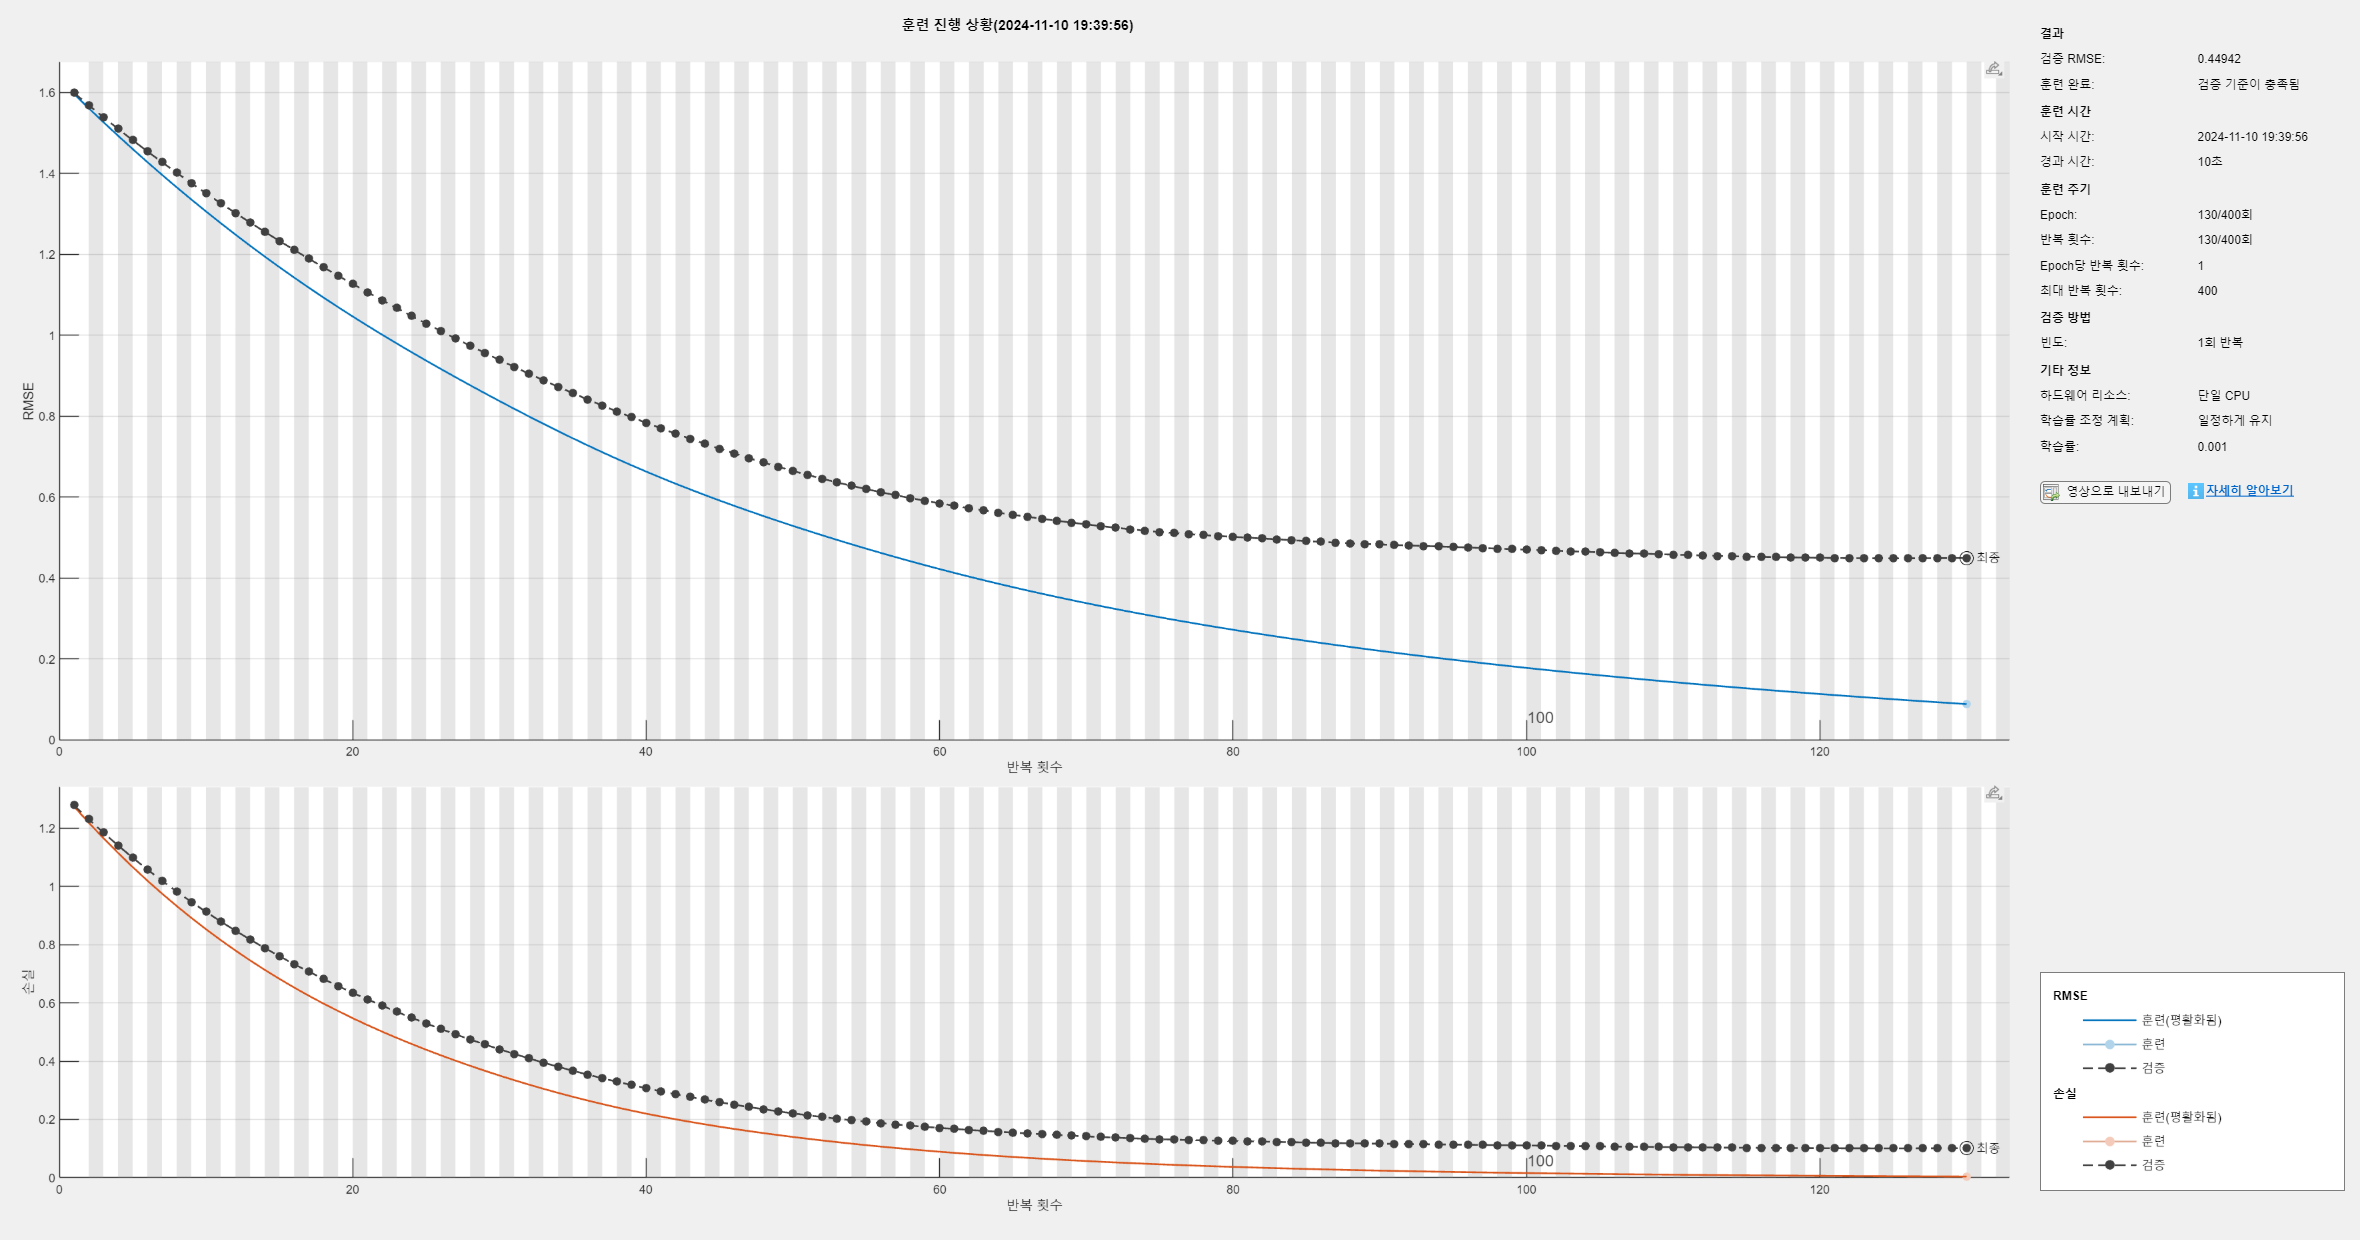

% (1) Train position
net_pos = trainNetwork(data_train',pos_train',layers,options);

#### `!!!Fill the blank!!!`

`[Hint] LSTM expects the data format to be (features x time steps). Transpose the data to match this format.`

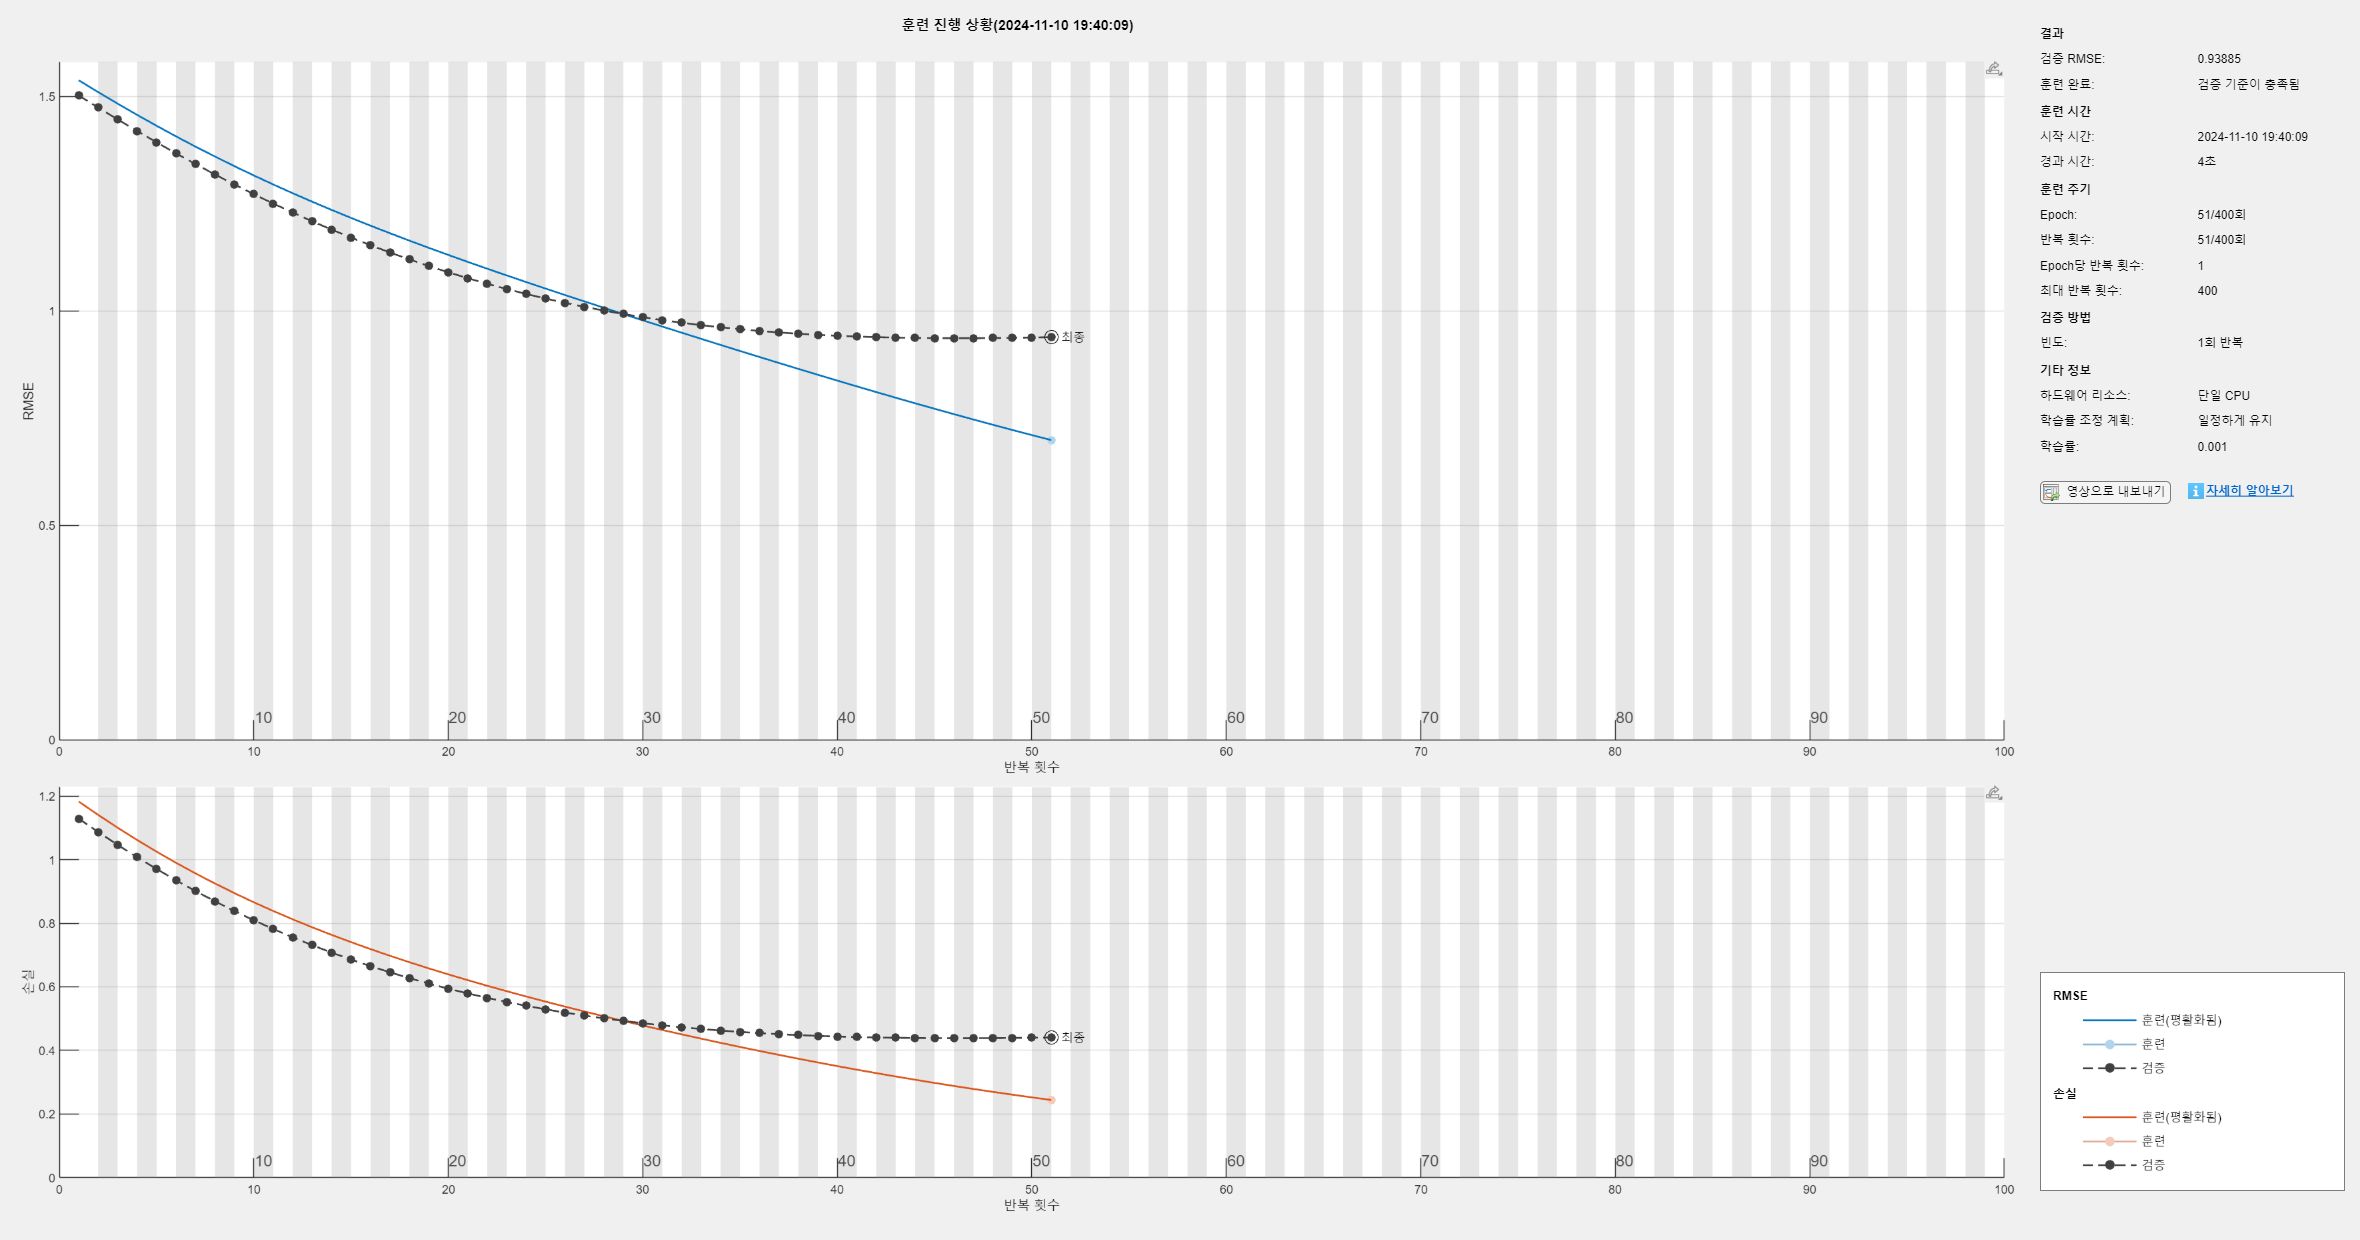

% (2) Train velocity
net_vel = trainNetwork(data_train_v',vel_train',layers,options);

**Test**

% Test set indexing
data_test   = Z_FR(idx_test);
pos_test    = Z_Pos(idx_test);
vel_test    = Z_Vel(idx_test);

n_trial     = length(data_test);
pos_pred    = cell(n_trial,1);
pos_rec     = cell(n_trial,1);
vel_pred    = cell(n_trial,1);

for trial = 1:n_trial
    % (1) Postion
    x_test = data_test{trial}(:,~idx_mask);

#### `!!!Fill the blank!!!`

    pos_pred{trial} = predict(net_pos,x_test',"MiniBatchSize",mini_batch_size)'; % Get position

    % for plot
    figure(1)
    subplot(sub_dim(1),sub_dim(2),trial)
    hold on
    plot(pos_pred{trial}(1,1),pos_pred{trial}(1,2),'.','color',"#D95319",'MarkerSize',20)
    plot(pos_pred{trial}(:,1),pos_pred{trial}(:,2),'color',	"#D95319",'LineWidth',1.2)
    xlim([-2.5 2.5])
    ylim([-2.5 2.5])


    % (2) Velocity
    x_test = data_test{trial}(:,~idx_mask);
    x_test(1,:) = [];                       % Remove first time point

#### `!!!Fill the blank!!!`

    vel_tmp = predict(net_vel,x_test',"MiniBatchSize",mini_batch_size)';

    % Reconstruct position by adding velocity
    pos_rec{trial} = pos_test{trial}(1,:);         % Get starting position
    vel_pred{trial} = vel_tmp.*std_vel + mean_vel; % Return to original value

    n_t = length(vel_pred{trial});
    for i = 1:n_t
        % tmp_rec: add current time point velocity to previous pos_rec
        tmp_rec = [pos_rec{trial}(i,1)+vel_pred{trial}(i,1) pos_rec{trial}(i,2)+vel_pred{trial}(i,2)];
        pos_rec{trial} = [pos_rec{trial}; tmp_rec];
    end

    % for plot
    figure(2)
    subplot(sub_dim(1),sub_dim(2),trial)
    hold on
    plot(pos_rec{trial}(1,1),pos_rec{trial}(1,2),'.','color',"#D95319",'MarkerSize',20)
    plot(pos_rec{trial}(:,1),pos_rec{trial}(:,2),'color',"#D95319",'LineWidth',1.2)
    xlim([-2.5 2.5])
    ylim([-2.5 2.5])
end

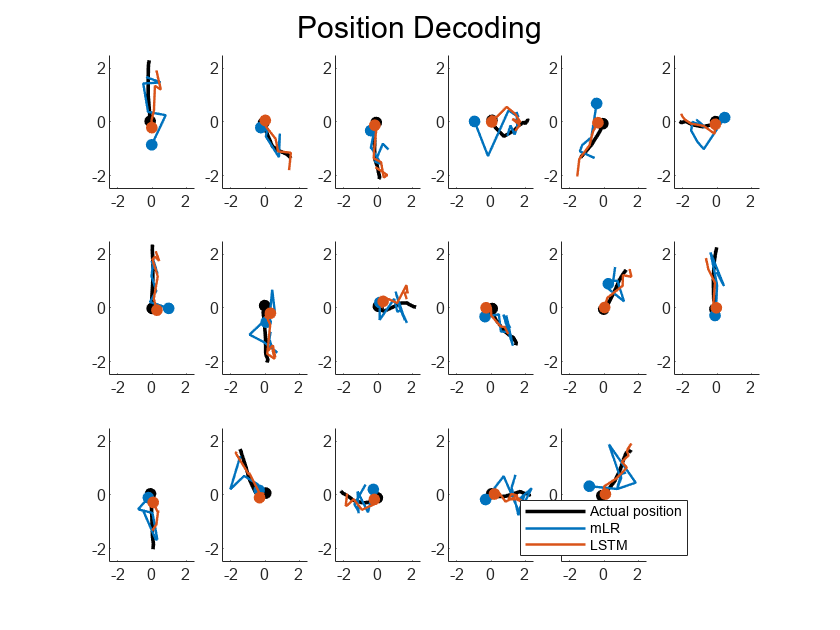

figure(1)
legend('','Actual position','','mLR','','LSTM','Location','Best')

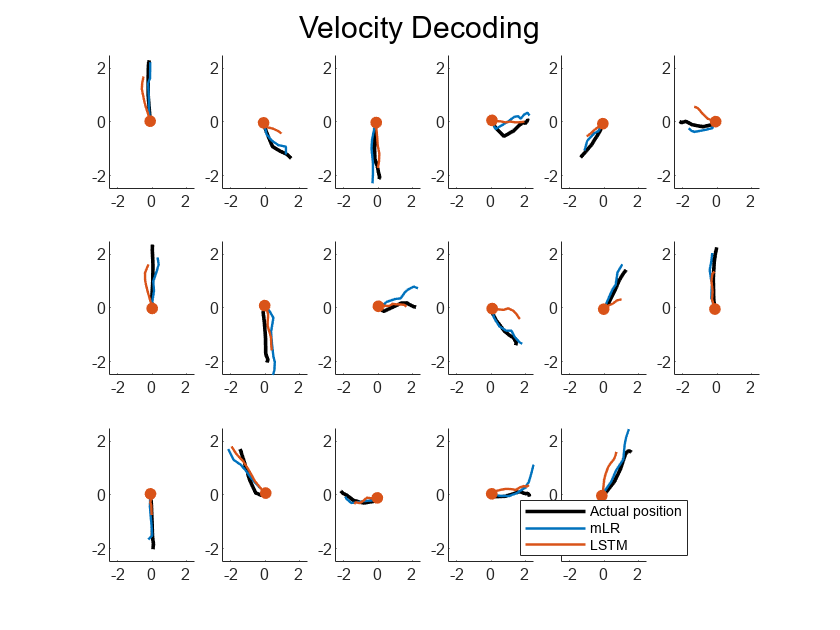

figure(2)
legend('','Actual position','','mLR','','LSTM','Location','Best')

**LSTM Evaluation**

% Original
tmp = cell2mat(pos_test);
x_pos = tmp(:,1);
y_pos = tmp(:,2);

% (1) For position
tmp = cell2mat(pos_pred);
xhat_pos = tmp(:,1);
yhat_pos = tmp(:,2);

% Get mean absolute error between original and predicted
MAE_pos_x = sum(abs(x_pos - xhat_pos))/length(x_pos);
MAE_pos_y = sum(abs(y_pos - yhat_pos))/length(y_pos);

% Get correlation between original and predicted
CC_pos_x = corr(x_pos,xhat_pos);
CC_pos_y = corr(y_pos,yhat_pos);

% (2) For velocity
tmp = cell2mat(pos_rec);
xhat_vel = tmp(:,1);
yhat_vel = tmp(:,2);

% Get mean absolute error between original and predicted
MAE_vel_x = sum(abs(x_pos - xhat_vel))/length(x_pos);
MAE_vel_y = sum(abs(y_pos - yhat_vel))/length(y_pos);

% Get correlation between original and predicted
CC_vel_x = corr(x_pos,xhat_vel);
CC_vel_y = corr(y_pos,yhat_vel);

**LSTM Decoding Results**

% Position Decoding Evaluation
position_results = table(["x-axis"; "y-axis"; "average"], ...
                         [MAE_pos_x; MAE_pos_y; (MAE_pos_x + MAE_pos_y) / 2], ...
                         [CC_pos_x; CC_pos_y; (CC_pos_x + CC_pos_y) / 2], ...
                         'VariableNames', {'axis', 'MAE', 'CC'});

disp(position_results)

      axis         MAE        CC   
    _________    _______    _______

    "x-axis"     0.25052    0.94879
    "y-axis"     0.24567     0.9509
    "average"     0.2481    0.94984



% Velocity Decoding Evaluation
velocity_results = table(["x-axis"; "y-axis"; "average"], ...
                         [MAE_vel_x; MAE_vel_y; (MAE_vel_x + MAE_vel_y) / 2], ...
                         [CC_vel_x; CC_vel_y; (CC_vel_x + CC_vel_y) / 2], ...
                         'VariableNames', {'axis', 'MAE', 'CC'});

disp(velocity_results)

      axis         MAE        CC   
    _________    _______    _______

    "x-axis"     0.26647    0.95115
    "y-axis"     0.37274    0.92693
    "average"    0.31961    0.93904

